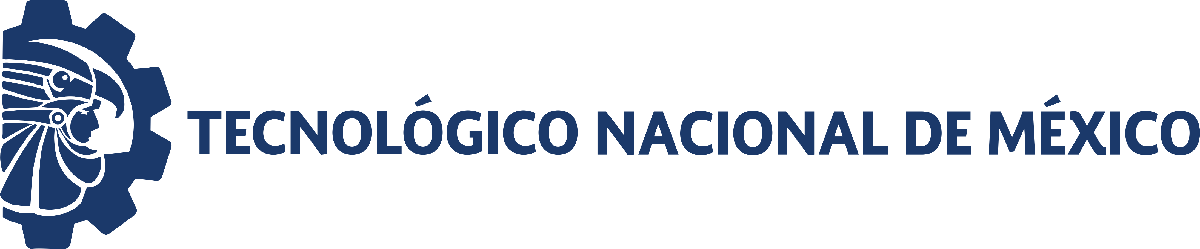                                 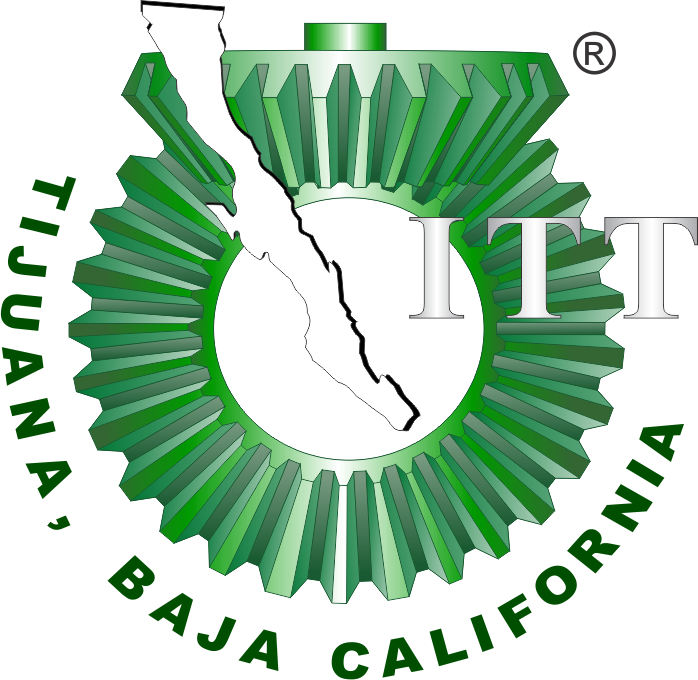

# Práctica 5.4: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

[Foto]

Nombre del alumno: **Erik Rasheed Rendón Carrillo **

Número de control: **20210818**

Correo institucional: **erik.rendonc201@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Practica_5_4';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode15s';
parameters.MaxStep = '1E-3';
set_param('Practica_5_4/Ppa(t)','Minimum','-0.2');
set_param('Practica_5_4/Ppa(t)','Maximum','1');
set_param('Practica_5_4/Ppa(t)','Seed','106');
set_param('Practica_5_4/Ppa(t)','SampleTime','0.5');
x = sim(file,parameters);

Found algebraic loop that contains: 
Practica_5_4/Pp(t): Hipotenso/z*r//z+r
Practica_5_4/Pp(t): Hipotenso/Derivative
Practica_5_4/Pp(t): Hipotenso/C
Practica_5_4/Pp(t): Hipotenso/Add (algebraic variable)
Found algebraic loop that contains: 
Practica_5_4/Normotenso1/z*r//z+r
Practica_5_4/Normotenso1/Derivative
Practica_5_4/Normotenso1/C
<a hre

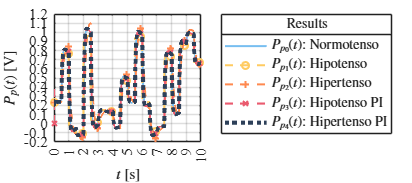

writematrix(x.Ppa,'signal.xlsx')
plotsignals(x.tout,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4,'Lazo Cerrado')

x1 = sim(file,parameters);

Found algebraic loop that contains: 
Practica_5_4/Pp(t): Hipotenso/z*r//z+r
Practica_5_4/Pp(t): Hipotenso/Derivative
Practica_5_4/Pp(t): Hipotenso/C
Practica_5_4/Pp(t): Hipotenso/Add (algebraic variable)
Found algebraic loop that contains: 
Practica_5_4/Normotenso1/z*r//z+r
Practica_5_4/Normotenso1/Derivative
Practica_5_4/Normotenso1/C
<a hre

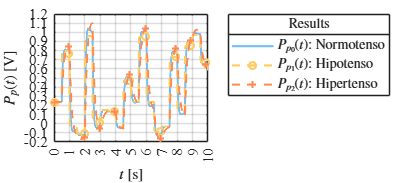

plotsignals(x1.tout, x1.Pp0, x1.Pp1, x1.Pp2, [], [], 'Lazo abierto');

## **Función: Respuesta a las señales**

function plotsignals(tout, Pp0, Pp1, Pp2, Pp3, Pp4, nombre)
    set(figure(),'Color','w')
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid on; box on;

    mycolors = [119,190,240;
                255,203,97;
                255,137,79;
                234,91,111;
                45,64,89;
                6,66,50]/255;
    colororder(mycolors)

    vars = {Pp0, Pp1, Pp2, Pp3, Pp4};
    labels = {'$P_{p_0}(t)$: Normotenso', ...
              '$P_{p_1}(t)$: Hipotenso', ...
              '$P_{p_2}(t)$: Hipertenso', ...
              '$P_{p_3}(t)$: Hipotenso PI', ...
              '$P_{p_4}(t)$: Hipertenso PI'};
    estilos = {'-', '--o', '--+', '--x', ':'};

    p = [];
    for i = 1:length(vars)
        if ~isempty(vars{i})
            p(end+1) = plot(tout, vars{i}, estilos{i}, 'LineWidth', 1.5, ...
                'MarkerSize', 5, 'MarkerIndices', 1:1000:length(tout));
        end
    end

    if length(p) >= 5
        set(p(5),'LineWidth',3);
    end

    L = legend(p, labels{1:length(p)}, 'Interpreter', 'Latex', ...
        'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    title(L, 'Results', 'FontSize', 10);

    xlabel('$t$ [s]', 'Interpreter', 'Latex', 'FontSize', 11)
    ylabel('$P_p(t)$ [V]', 'Interpreter', 'Latex', 'FontSize', 11)

    xlim([0,10]); xticks(0:1:10);
    ylim([-0.2,1.2]); yticks(-0.2:0.1:1.2);

     exportgraphics(gcf, [nombre '.pdf'], 'ContentType', 'vector');
    exportgraphics(gcf, [nombre '.png'], 'ContentType', 'vector');
end
